clc;
% Define the base directory
baseDir = 'C:\Users\Dell\Desktop\Project MSC Third Sem\MATLAB Files\Scripts\Datasets';

% Define the subdirectories for Islanding and Non-Islanding images
islandingDir = fullfile(baseDir, 'Islanding');
nonIslandingDir = fullfile(baseDir, 'Non-Islanding');

% Create a custom datastore for preprocessing
imds = imageDatastore({islandingDir, nonIslandingDir}, ...
    'IncludeSubfolders', true, ...
    'LabelSource', 'foldernames', ...
    'ReadFcn', @(filename) preprocessImage(imread(filename)));

% Display some information about the datastore
fprintf('Total number of images: %d\n', numel(imds.Files));

Total number of images: 2100


fprintf('Labels: %s\n', strjoin(string(unique(imds.Labels)), ', '));

Labels: Islanding, Non-Islanding


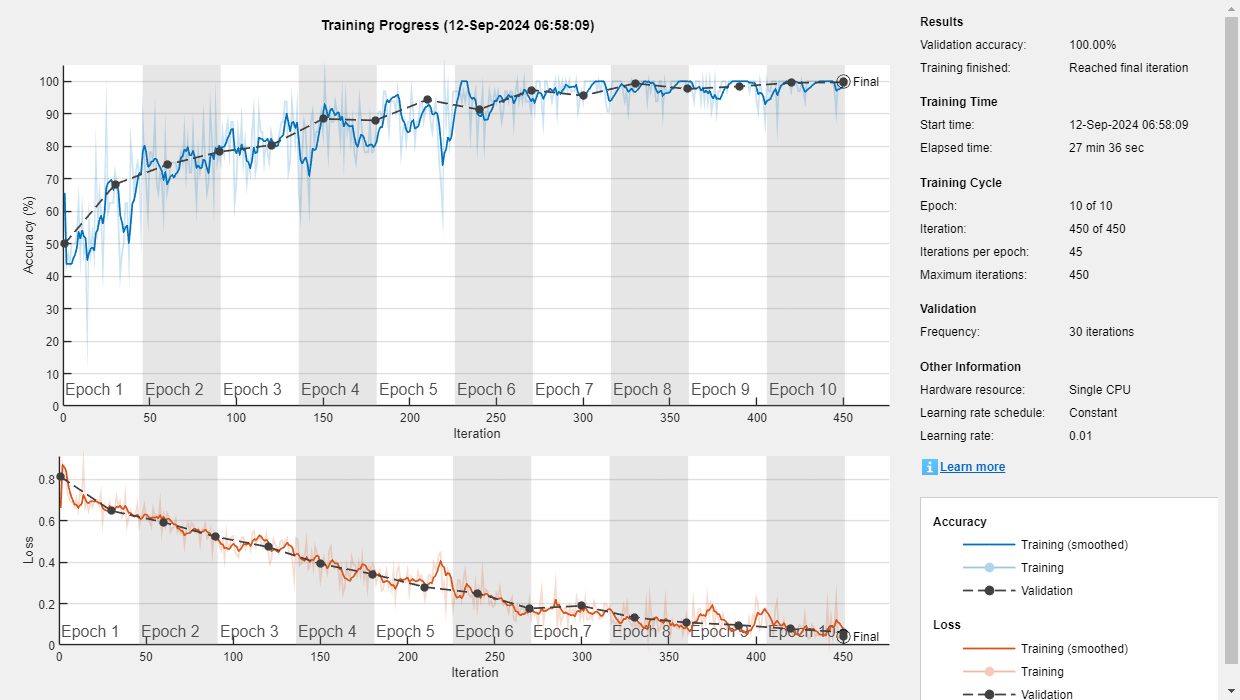


% Define a simpler CNN architecture
layers = [
    imageInputLayer([224 224 3])
    
    convolution2dLayer(3, 16, 'Padding', 'same')
    batchNormalizationLayer
    reluLayer
    maxPooling2dLayer(2, 'Stride', 2)
    
    convolution2dLayer(3, 32, 'Padding', 'same')
    batchNormalizationLayer
    reluLayer
    maxPooling2dLayer(2, 'Stride', 2)
    
    convolution2dLayer(3, 64, 'Padding', 'same')
    batchNormalizationLayer
    reluLayer
    
    globalAveragePooling2dLayer
    fullyConnectedLayer(2)
    softmaxLayer
    classificationLayer
];

% Split the data into training and validation sets
[trainingSet, validationSet] = splitEachLabel(imds, 0.7, 'randomized');

% Define training options (using CPU)
options = trainingOptions('sgdm', ...
    'InitialLearnRate', 0.01, ...
    'MaxEpochs', 10, ...
    'MiniBatchSize', 32, ...
    'Shuffle', 'every-epoch', ...
    'ValidationData', validationSet, ...
    'ValidationFrequency', 30, ...
    'Verbose', false, ...
    'Plots', 'training-progress', ...
    'ExecutionEnvironment', 'cpu');

% Train the network
net = trainNetwork(trainingSet, layers, options);


% Classify validation images
[YPred, probs] = classify(net, validationSet);

accuracy = mean(YPred == validationSet.Labels);

fprintf('Validation Accuracy: %f%%\n', accuracy * 100);

Validation Accuracy: 100.000000%


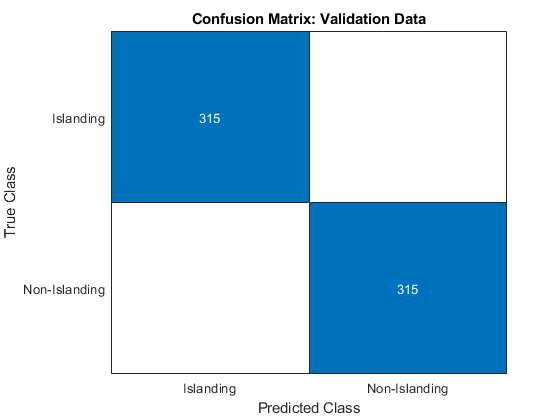


% Confusion Matrix
figure
confusionchart(validationSet.Labels, YPred);
title('Confusion Matrix: Validation Data');

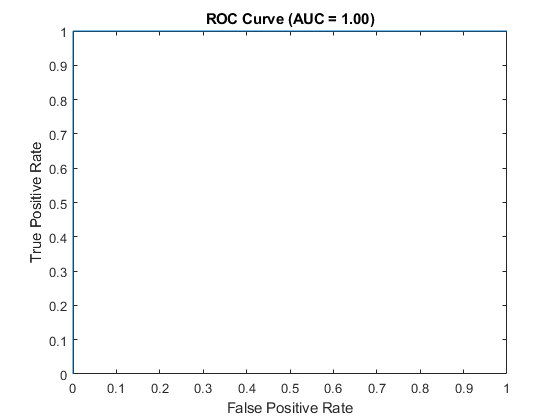


% ROC Curve
[X, Y, T, AUC] = perfcurve(validationSet.Labels, probs(:, 1), 'Islanding');
figure
plot(X, Y)
xlabel('False Positive Rate')
ylabel('True Positive Rate')
title(sprintf('ROC Curve (AUC = %.2f)', AUC))

save('trainedmodel.mat','net');

load('trainedmodel.mat');
% Example usage of classifyNewImage:
classifyNewImage(net, 'C:\Users\Dell\Desktop\Project MSC Third Sem\MATLAB Files\Scripts\testimages\2is.png');

Image classified as: Islanding
Probability: 97.65%


% Function definitions below this point

function preprocessedImg = preprocessImage(img)
    % Resize image to a smaller dimension
    img = imresize(img, [224 224]);
    % Convert to single precision and scale to [0, 1]
    img = im2single(img);
    % Normalize to zero mean and unit variance
    img = (img - mean(img(:))) / std(img(:));
    preprocessedImg = img;
end

function classifyNewImage(net, imagePath)
    try
        % Check if the file exists
        if ~exist(imagePath, 'file')
            error('File does not exist: %s', imagePath);
        end
        
        % Try to read the image
        img = imread(imagePath);
        
        % If successful, proceed with classification
        img = preprocessImage(img);
        [label, prob] = classify(net, img);
        fprintf('Image classified as: %s\n', char(label));
        fprintf('Probability: %.2f%%\n', max(prob) * 100);
    catch ME
        % If an error occurs, provide more detailed information
        fprintf('Error occurred while trying to classify the image:\n');
        fprintf('Error message: %s\n', ME.message);
        
        % Additional debugging information
        fprintf('Full file path: %s\n', fullfile(pwd, imagePath));
        fprintf('Current directory: %s\n', pwd);
        
        % Check file information
        if exist(imagePath, 'file')
            fileInfo = dir(imagePath);
            fprintf('File size: %d bytes\n', fileInfo.bytes);
            fprintf('Last modified: %s\n', datestr(fileInfo.datenum));
            fprintf('File attributes: %s\n', fileInfo.bytes);
        end
        
        % Suggest possible solutions
        fprintf('\nPossible solutions:\n');
        fprintf('1. Ensure the file path is correct and the image exists.\n');
        fprintf('2. Check if you have read permissions for the file and directory.\n');
        fprintf('3. Try using the full absolute path to the image.\n');
        fprintf('4. Ensure the image is a valid format (e.g., .jpg, .png).\n');
        
        % Additional check for file readability
        if exist(imagePath, 'file')
            fid = fopen(imagePath, 'r');
            if fid == -1
                fprintf('Unable to open the file for reading. Check file permissions.\n');
            else
                fclose(fid);
                fprintf('File can be opened for reading.\n');
            end
        end
    end
end